# Linear Control Design II - Group Work Problem Module 7 

                Roberto Galeazzi (2015), Hjalte Bested Møller (2017)

		        Department of Electrical Engineering 

                            Technical University of Denmark 

                                        August, 2017

## Description	

A system with three interconnected tanks is shown in Fig.1. The tanks have the cross sectional areas $A_1$, $A_2$ and $A_3$. The input flows are proportional to the input voltages, that is


$$q_a = k u_1$$



$$q_b = k u_2$$


The flows follow the square root law and since the pressures in the bottoms of the tanks are proportional to the level, one has 


$$q_1 = c_1 \sqrt{x_1-x_2}$$



$$q_2 = c_2 \sqrt{x3-x2}$$



$$q_0 = c_0 \sqrt{x_2}$$


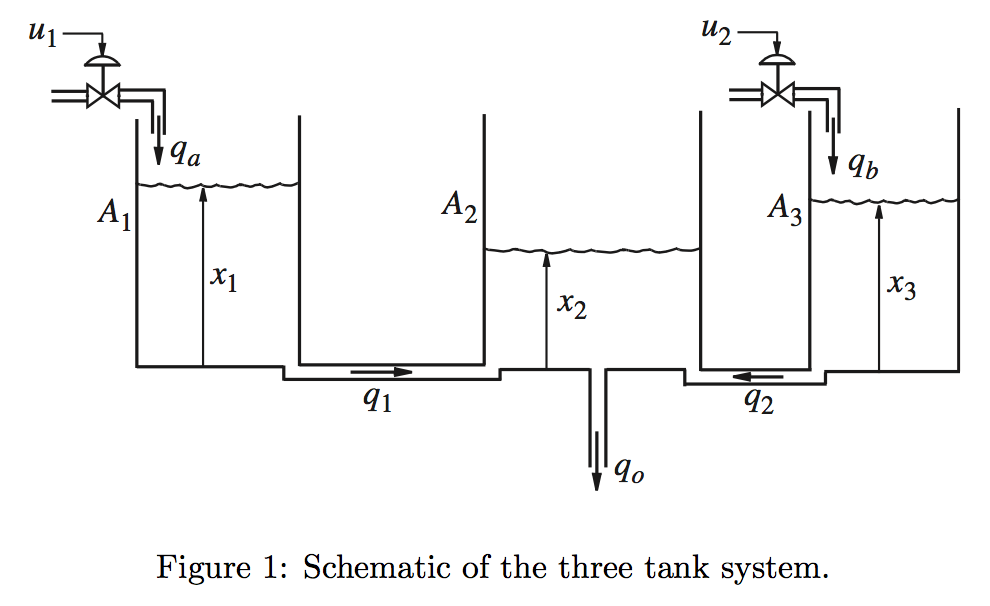				

**Problem 1**  Derive the set of equations describing the system and formulate the nonlinear state model with the two inputs $u_1$ and $u_2$, and the output = $q_0$. 

% Your solution goes here:
syms k u1 u2 q1 q2 q_o q_a q_b c1 c2 c_o x1 x2 x3 A1 A2 A3
q_a = k*u1;
q_b = k*u2;
q1 = c1*sqrt(x1-x2);
q2 = c2*sqrt(x3-x2);
q_o = c_o*sqrt(x2);
x1_d = (q_a-q1)/A1;
x2_d = (q1+q2-q_o)/A2;
x3_d = (q_b-q2)/A3;

x = [x1; x2; x3]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)$$

u = [u1;u2]

$$u = \left(\begin{array}{c} u_{1}\\ u_{2} \end{array}\right)$$

f([x; u]) = [x1_d; x2_d; x3_d]

$$f(x1, x2, x3, u1, u2) = \left(\begin{array}{c} \frac{k\,u_{1}-c_{1}\,\sqrt{x_{1}-x_{2}}}{A_{1}}\\ \frac{c_{1}\,\sqrt{x_{1}-x_{2}}-c_{o}\,\sqrt{x_{2}}+c_{2}\,\sqrt{x_{3}-x_{2}}}{A_{2}}\\ \frac{k\,u_{2}-c_{2}\,\sqrt{x_{3}-x_{2}}}{A_{3}} \end{array}\right)$$

g([x; u]) = [q_o]

$$g(x1, x2, x3, u1, u2) = c_{o}\,\sqrt{x_{2}}$$

**Problem 2**  Find the stationary point under the assumption that the inputs are $u_1 = u_{10}$ and $u_2 = u_{20}$. 					

% Your solution goes here:
syms u10 u20 x10 x20 x30
u0 = [u10; u20];


$$\dot{x_1 } =0\Rightarrow k\text{ }u_{10} =c_1 \text{ }\sqrt{\text{ }x_{10} -x_{20} }$$



$$\dot{x_2 } =0\Rightarrow c_0 \sqrt{x_{20} }=c_1 \sqrt{x_{10} -x_{20} }+c_2 \sqrt{x_{30} -x_{20} }\Rightarrow c_0 \sqrt{x_{20} }=k{\text{ }u}_{10} +{k\text{ }u}_{20}$$



$$\dot{x_3 } =0\Rightarrow k\text{ }u_{20} =c_2 \sqrt{x_{30} -x_{20} }$$


x10 = x20+k^2*u10^2/c1^2

$$x10 = x_{20}+\frac{k^{2}\,{u_{10}}^{2}}{{c_{1}}^{2}}$$

x20 = (k*(u10+u20)/c_o)^2

$$x20 = \frac{k^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{c_{o}}^{2}}$$

x30 = x20+k^2*u20^2/c2^2

$$x30 = \frac{k^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{c_{o}}^{2}}+\frac{k^{2}\,{u_{20}}^{2}}{{c_{2}}^{2}}$$

y0 = c_o*sqrt(x20)

$$y0 = c_{o}\,\sqrt{\frac{k^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{c_{o}}^{2}}}$$

**Problem 3**  Linearize the model and derive the linear state space model

            Process equation:  $\Delta \dot{\mathbf{x}} =\mathbf{A} \Delta \mathbf{x} + \mathbf{B} \Delta \mathbf{u}$

            Output equation:    $\Delta \mathbf{y} = \mathbf{C} \Delta \mathbf{x}$

% Your solution goes here:

A = subs([diff(x1_d, x1) diff(x1_d, x2) diff(x1_d, x3);  ...
          diff(x2_d, x1) diff(x2_d, x2) diff(x2_d, x3);  ...
          diff(x3_d, x1) diff(x3_d, x2) diff(x3_d, x3)], ...
          [x1 x2 x3 u1 u2], [x10 x20 x30 u10 u20])

$$A = \begin{array}{l} \left(\begin{array}{ccc} -\frac{c_{1}}{2\,A_{1}\,\sigma_{1}} & \frac{c_{1}}{2\,A_{1}\,\sigma_{1}} & 0\\ \frac{c_{1}}{2\,A_{2}\,\sigma_{1}} & -\frac{\frac{c_{1}}{2\,\sigma_{1}}+\frac{c_{o}}{2\,\sqrt{\frac{k^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{c_{o}}^{2}}}}+\frac{c_{2}}{2\,\sigma_{2}}}{A_{2}} & \frac{c_{2}}{2\,A_{2}\,\sigma_{2}}\\ 0 & \frac{c_{2}}{2\,A_{3}\,\sigma_{2}} & -\frac{c_{2}}{2\,A_{3}\,\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{x_{20}-\frac{k^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{c_{o}}^{2}}+\frac{k^{2}\,{u_{10}}^{2}}{{c_{1}}^{2}}}\\ \sigma_{2}=\sqrt{\frac{k^{2}\,{u_{20}}^{2}}{{c_{2}}^{2}}} \end{array}$$

B = subs([diff(x1_d, u1) diff(x1_d, u2);  ...
          diff(x2_d, u1) diff(x2_d, u2);  ...
          diff(x3_d, u1) diff(x3_d, u2)], ...
          [x1 x2 x3 u1 u2], [x10 x20 x30 u10 u20])

$$B = \left(\begin{array}{cc} \frac{k}{A_{1}} & 0\\ 0 & 0\\ 0 & \frac{k}{A_{3}} \end{array}\right)$$

C = subs([diff(q_o, x1) diff(q_o, x2) diff(q_o, x3)], ...
          [x1 x2 x3 u1 u2], [x10 x20 x30 u10 u20])

$$C = \left(\begin{array}{ccc} 0 & \frac{c_{o}}{2\,\sqrt{\frac{k^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{c_{o}}^{2}}}} & 0 \end{array}\right)$$

D = [diff(q_o,u1) diff(q_o,u2)]

$$D = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

Table 1 shows the numerical value of the system’s parameters. The working interval of the input voltages $u_1$ and $u_2$ is 0-10 volts. 

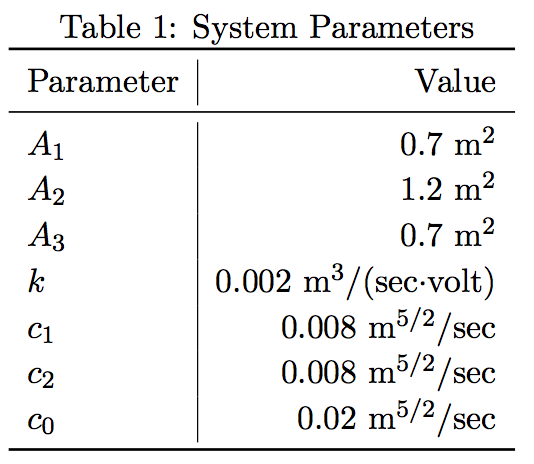

% Define System parameters:
A1 = 0.7;
A2 = 1.2;
A3 = 0.7; 

k = .002; 

c1 = .008; 
c2 = .008;
c_o = .02;

% Your solution goes here:
u10 = 5;
u20 = 5;
x20 = (k*(u10+u20)/c_o)^2;
x10 = x20+k^2*u10^2/c1^2;
x30 = x20+k^2*u20^2/c2^2;
A_r = subs(A)

$$A\_r = \left(\begin{array}{ccc} -\frac{4}{875} & \frac{4}{875} & 0\\ \frac{1}{375} & -\frac{41}{3000} & \frac{1}{375}\\ 0 & \frac{4}{875} & -\frac{4}{875} \end{array}\right)$$

B_r = subs(B)

$$B\_r = \left(\begin{array}{cc} \frac{1}{350} & 0\\ 0 & 0\\ 0 & \frac{1}{350} \end{array}\right)$$

C_r = subs(C)

$$C\_r = \left(\begin{array}{ccc} 0 & \frac{1}{100} & 0 \end{array}\right)$$

**Problem 4 ** Set up a Simulink model of the nonlinear system and write a MatLab script to initialize the model with the needed parameter values. Remember that all input variables must be provided with an in port, and all output variables must be provided with an out port in the model. 

clear
% Define System parameters:
A1 = 0.7;
A2 = 1.2;
A3 = 0.7; 

k = .002; 

c1 = .008; 
c2 = .008;
c0 = .02;

% Your solution goes here:



**Problem 5**  Linearize the model using linmod. Set both inputs $u_1 = u_2 = 5$ volts. Simulink by default determine the numbering of the states in the model when linmod is used. It can be a little confusing when comparing Simulinks results with those obtained by manual calculations. If desired, one can determine one’s own numbering in the following way: 

- Choose an integrator in the model and do a right-button click 

- Choose Block Properties. A window opens

- Write the number desired in the Priority-field

- Close the Block Properties window 

% Your solution goes here:




**Problem 6 ** Simulate the nonlinear and linearized model for small and large variations of the system’s inputs $u_1$ and $u_2$ around their stationary values. Plot the state and output responses and try to determine which is the range of input variations where the linearized model is a good approximation of the nonlinear system. 

% Your solution goes here:




**Problem 7**  Determine the transfer functions from u1 to y and from u2 to y. 

% Your solution goes here:




**Problem 8**  Assess the internal and external stability of the system. 

% Your solution goes here:




**Problem 9**  Expand the Matlab script to compute the eigenvalues of the linearized system for input values in the entire interval 0-10 volts. Analyse the behaviour of the system eigenvalues as function of the operating point of the system. Hint: Include a for-loop which will find the stationary states by simulation over 5000 seconds for each value of $u$ (use the MATLAB function sim to simulate the system within the for-loop). Then linearize the model for each value using the final states (xFinal) as the stationary values. 

% Your solution goes here:




**Problem 10**  Choose a suitable sampling time $T_s$ and discretize the system obtained in Problem 5 using the Matlab$\mathtt{c2d}$-function. Calculate the eigenvalues of the discretized system both using the Matlab $\mathtt{eig}$-function and Frobenius theorem. Compare the obtained results. Is the discretization changing the stability properties of the system? 

% Your solution goes here:


